 
 Iteration   Func-count         f(x)         Procedure
     0            1      3.25892e+06         
     1            3      2.95237e+06         initial simplex
     2            5       2.7414e+06         expand
     3            7      2.29137e+06         expand
     4            9      1.86012e+06         expand
     5           11      1.28022e+06         expand
     6           13           816262         expand
     7           15           428546         expand
     8           17           205547         expand
     9           19          83842.8         expand
    10           21          31559.8         expand
    11           23          10320.7         expand
    12           25           2963.8         expand
    13           27          678.448         expand
    14           29          166.523         expand
    15           31          140.475         reflect
    16           33          140.475         contract outside
    17           35          140.475         

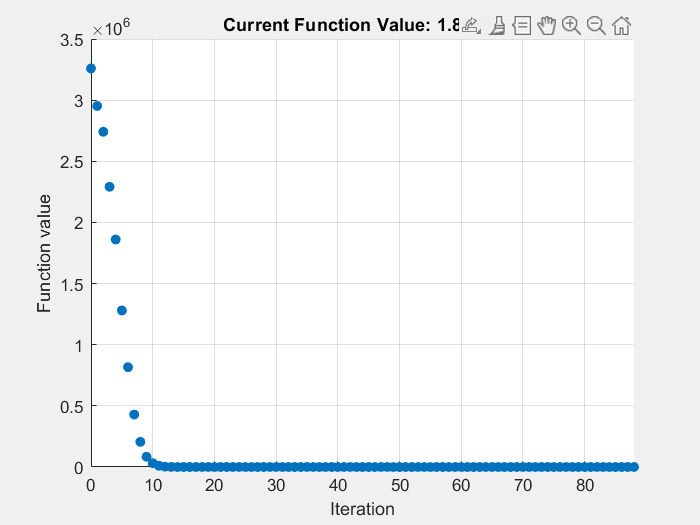

x =     3.0444    1.2448


fval = 1.8069

exitflag = 1

clear


x0 = [1,0]; %definiuje się wektor startowy zależy od stopnia estymowanego obiektu
fun = @ident;
options = optimset('Display','iter','PlotFcns',@optimplotfval);
[x,fval,exitflag] = fminsearch(fun,x0,options)

G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p %obiekt podstawowy

G1 =
 
                   -s^3 + 24 s^2 - 240 s + 960
  --------------------------------------------------------------
  s^6 + 26 s^5 + 290.2 s^4 + 1495 s^3 + 2490 s^2 + 2460 s + 1200
 
Continuous-time transfer function.
Model Properties


G2=tf([0 1],[x(1) x(2)])  %wypisanie obiektu estymowanego

G2 =
 
         1
  ---------------
  3.044 s + 1.245
 
Continuous-time transfer function.
Model Properties





b=G2.Numerator{1, 1}

b =      0     1


a=G2.Denominator{1,1}

a =     3.0444    1.2448


[z,p,k] =tf2zp(b,a)


z =

  0×1 empty double column vector



p = -0.4089

k = 0.3285

function blad = ident(x)

t=0:0.1:100;
G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p;


G2=tf([0 1],[x(1) x(2)]);
[y1] = step(G1,t); % wzor
[y2] = step(G2,t); % dopasowanie


e = y1-y2;
blad= sum(e.^2);
%blad= sum(e.^2) / length(e);
end
